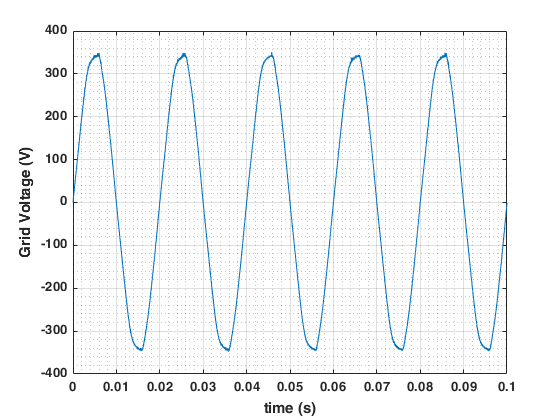

%%% FIRST RUN a.load_data.mlx;

measurement = meas2;

grid_voltage_real = -measurement.V_ch1; 
time_vector = measurement.Timestamp;

plot(time_vector, grid_voltage_real);
xlabel("time (s)"); ylabel("Grid Voltage (V)");
grid on; grid minor;

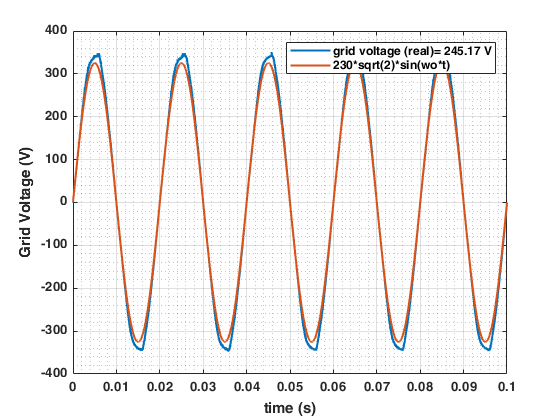


w0 = (50*2*pi());
grid_voltage_expected = 230*sqrt(2)*sin(time_vector.*w0);

plot(time_vector, grid_voltage_real, 'LineWidth', 1.5); 
hold on; plot(time_vector, grid_voltage_expected, 'LineWidth', 1.5); 
legend(strcat("grid voltage (real)= ", num2str(rms(grid_voltage_real), '%.2f'), " V"), "230*sqrt(2)*sin(wo*t)");
xlabel("time (s)"); ylabel("Grid Voltage (V)");
grid on; grid minor;

hold off;

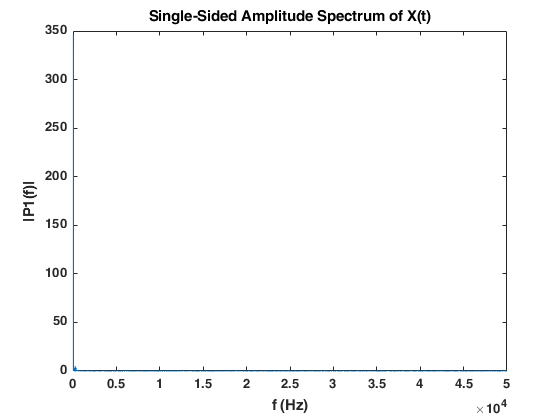


% grid_voltage_diff = grid_voltage_real-grid_voltage_expected;
% plot(time_vector, grid_voltage_diff); 
% xlabel("time (s)"); ylabel("Grid Voltage difference (V)");
% grid on; grid minor;

%%%% Spectrum Analysis
x = grid_voltage_real;
Fs = length(grid_voltage_real)*10;
L = length(x);
Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

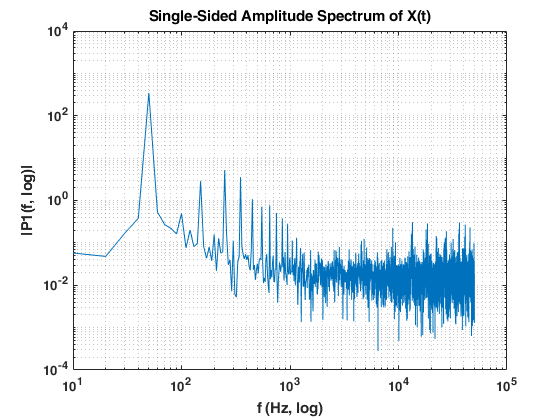

%xlim([0 1000]);
loglog(f,P1); grid minor;
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz, log)')
ylabel('|P1(f, log)|')

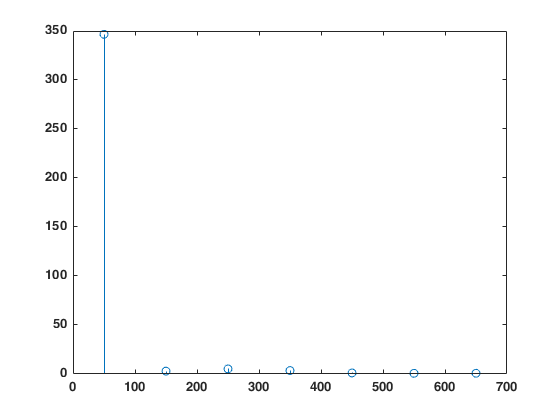

% %%% apresentar os valores em percentagem da fundamental
% plot(f,(P1./P1(6)).*100) 
% title('Single-Sided Amplitude Spectrum of X(t)')
% xlabel('f (Hz)')
% ylabel('|P1(f)|')
% xlim([0 1000]);

%%%% Harmonic analysis
h_1= 1*5+1; 
h_3 = 3*5+1;
h_5 = 5*5+1;
h_7 = 7*5+1;
h_9 = 9*5+1;
h_11 = 11*5+1;
h_13 = 13*5+1;

stem([50 150 250 350 450 550 650], P1([h_1 h_3 h_5 h_7 h_9 h_11 h_13]))

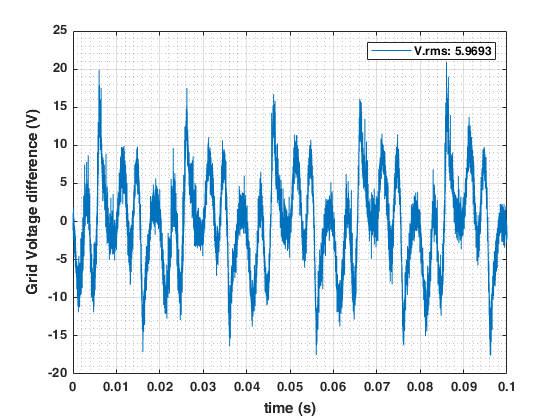

grid_voltage_expected = P1(h_1)*sin(time_vector.*w0);
grid_voltage_diff = grid_voltage_real-grid_voltage_expected;
grid_voltage_diff = grid_voltage_real-grid_voltage_expected;
plot(time_vector, grid_voltage_diff); 
legend(strcat("V.rms: ", num2str(rms(grid_voltage_diff))));
xlabel("time (s)"); ylabel("Grid Voltage difference (V)");
grid on; grid minor;


%%%THD = VRMS_no_50Hz/VRMS_50Hz
THD_grid_voltage = rms(grid_voltage_diff)/(P1(h_1)/sqrt(2));
fprintf("Value of THD: 100 * (V diff)/(V h1) = %.2f %%", THD_grid_voltage * 100);

Value of THD: 100 * (V diff)/(V h1) = 2.44 %

fprintf("Value of 5th harmonic = %.2f %%", (P1(h_5)/(P1(h_1)))*100);

Value of 5th harmonic = 1.50 %

**IEEE Std 519**, “RECOMMENDED PRACTICES AND REQUIREMENTS FOR HARMONIC CONTROL IN ELECTRICAL POWER SYSTEMS”:

[https://edisciplinas.usp.br/pluginfile.php/1589263/mod_resource/content/1/IEE%20Std%20519-2014.pdf](https://edisciplinas.usp.br/pluginfile.php/1589263/mod_resource/content/1/IEE%20Std%20519-2014.pdf)

Low voltage Systems: max THD = 8% and max individual harmonic = 5%







%%%functions
function measurement = importfile(filename, dataLines)

% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [2, Inf];
end

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Timemilliseconds", "scope4"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
measurement = readtable(filename, opts);

end